# Figure 2D

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files\A088_dataIF\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
        'siCtrl',2,2:11,1,[0 0 0],[0 10]; %1 
        'siCyclinA2',3,2:11,1,[0 0 0],[0 10]; %1 
        'siDBF4',4,2:11,1,[0 0 0],[0 10]; %1 
          
       }

conditions = 3×6 cell array
    {'siCtrl'    }    {[2]}    {[2 3 4 5 6 7 8 9 10 11]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'siCyclinA2'}    {[3]}    {[2 3 4 5 6 7 8 9 10 11]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'siDBF4'    }    {[4]}    {[2 3 4 5 6 7 8 9 10 11]}    {[1]}    {[0 0 0]}    {[0 10]}

S = loadData_IF(conditions, dataDir);

all_row = [2:7];
all_col = [2:11];


**Gate cells**

xthresh = 2.5e6;
xrange = linspace(0,5e6,1000);

for i = 1:length(S)
    S(i).dnaN = NaN*ones(size(S(i).DNA));
    for r = 1:8
        for c = 1:12
            inds = S(i).wellindex(:,1) == r & S(i).wellindex(:,2) == c;
            if sum(inds) > 0
                xdata = S(i).DNA(inds);
                [f, xi] = ksdensity(xdata,xrange);
                xi_trunc = xi(xi<xthresh);
                f_trunc = f(xi<xthresh);
                [~, maxi] = max(f_trunc);
                N_peak = xi_trunc(maxi);
                S(i).dnaN(inds) = 2*S(i).DNA(inds)/N_peak;
            end
        end
    end
end


% geminin background: 400
%cyclin a background: 490
%dbf4 background 4000

**DBF4, APC ON**

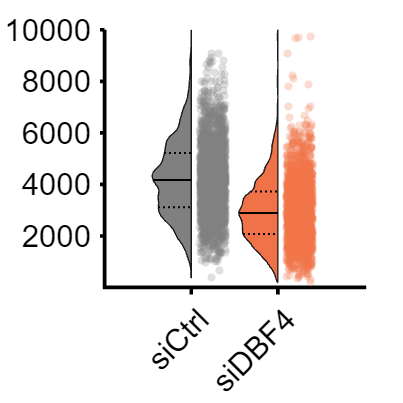

ans = 2000

ans = 2000

p = 1.4250e-108

conds=[1 3] ;
rng(5)
offset=0;
ally = [];
groups = [];
poi_list = [1];
yval = 'YFP3';

gateVals = {'dnaN','RFP1'};
rangeVals = {[0 2.5],[0 700]}; 
edges = linspace(12,14,30);
row_gate = [2:4];
col_gate = [7:11];

colors = [.5 .5 .5;.941 .447 .282;.4 .1 .5; 0 .7 1;.1 .4 1;];
  f1= figure('Units', 'Inches', 'Position', [0, 0, 4, 4]);
   hold on

name = {'mitosis'};

lims = {[0 6],[0 10],[0 6]};
for p = 1:length(poi_list)
    poiAligned=poi_list(p);
   
   
    
    for i=1:length(conds)
        
     
        ydata = [];
        plot_ydata=[];
     
     

     condition = conds(i);
    ydata = real((S(condition).(yval)-4000)); %.*S(condition).area);
     rows = S(condition).wellindex(:,1);
     cols = S(condition).wellindex(:,2);
    
    totalGate = true(size(ydata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
     
    end
    

    ydata = ydata(totalGate & any(rows == row_gate,2)  & any(cols == col_gate,2));
ydata = randsample(ydata,2000);
    
   
  
   plot_ydata = ydata;

    ally = [ally;  plot_ydata];
    groups = [groups; repmat(i,size( plot_ydata))];
    length( plot_ydata)




    end




       cols = repmat({colors(1,:),colors(2,:)}',1,1);
groupcol = repmat([colors([1 2 ],:)],1,1);
figure(f1)
h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1]);
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',.5)
set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 20,groupcol(groups,:),'filled','MarkerFaceAlpha',.25);

        set(gca,'linewidth',2,'fontsize',17)
    
xticklabels(conditions(conds,1))

  ylim([8 10000])
 xtickangle(45)
set(gca,'fontsize',17)
 p=mediantest(ally(groups==1),ally(groups==2))

% print_pdf(['fig_2D_DBF4si.pdf'])
end